# Extraction et utilisation des données de la base Perry

**Version 1.1**

*Pascal Denis - 21 mai 2021*

## Introduction

Dans cet exercise, vous allez apprendre à extraire des données d'une matrice contenant les données du [Perry's chemical engineer”s handbook](https://r2.vlereader.com/Reader?ean=9780071593137) [1]. D'autres produits, seront ajoutés en complément et en fonction des besoins à cette base. Cela vous permettra de savoir comment accèder à des données thermodynamiques et de comprendre la notion de structure associée.

Ces outils servent de support aux calculs des propriétés thermodynamiques et thermophysiques du cours de Génie des Procédés de 1re années. Ces données sont utilisables sur la palteforme WIMS de l'École Centrale de Marseille. 

## Chargement de la base de données

% The file Perry.mat must be in your path
% Chargement de la base de données : 
% load Perry ou load Perry.mat fontionne

load Perry.mat;

Dans la zone Workspace, vous avez désormais : 

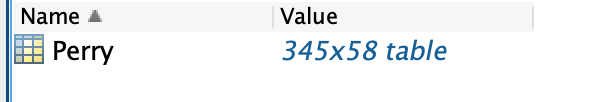

Fig. 1 Worksace

Il s'agit d'une table de 345 ligne et 58 colonnes contenant diverses informations. si vous faites un double clic sur Perry, les données de la tables s'ouvriront de la manière suivantes : 

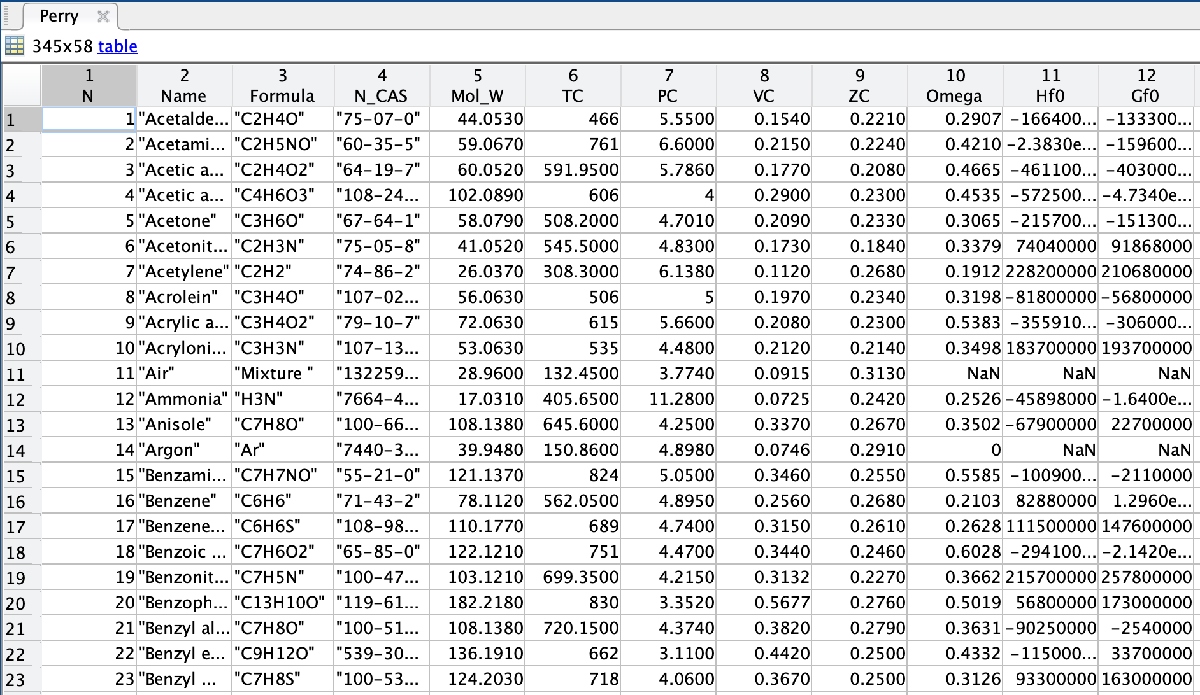

Par exemple pour i = 11, le composé est de l'air, c'est un moyen simple de connaitre un ID de produit dans la base. Vérifier que : 

- CO2 : 47 

- Méthane = 193 

- Eau (water)  = 342 

## Structure de la base de données

% Pour accéder aux différentes données stockées, nous allons regarder les
% propriétés associées à cette table

Properties = Perry.Properties

Properties =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {1×58 cell}
    VariableDescriptions: {1×58 cell}
           VariableUnits: {1×58 cell}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


% Pour avoir la liste des variables sous la forme d'un vecteur ligne : 

Perry.Properties.VariableNames

ans = 1×58 cell array
    {'N'}    {'Name'}    {'Formula'}    {'N_CAS'}    {'Mol_W'}    {'TC'}    {'PC'}    {'VC'}    {'ZC'}    {'Omega'}    {'Hf0'}    {'Gf0'}    {'Sf0'}    {'DH_Comb'}    {'CP_Gas1'}    {'CP_Gas2'}    {'CP_Gas3'}    {'CP_Gas4'}    {'CP_Gas5'}    {'T_CP_Gas_min'}    {'CP_Gas_Tmin'}    {'T_CP_Gas_max'}    {'CP_Gas_Tmax'}    {'H_Vap1'}    {'H_Vap2'}    {'H_Vap3'}    {'H_Vap4'}    {'T_H_Vap_min'}    {'DH_Vap_min'}    {'T_H_Vap_max'}    {'DH_Vap_max'}    {'Eq_CP_Liq'}    {'CP_Liq1'}    {'CP_Liq2'}    {'CP_Liq3'}    {'CP_Liq4'}    {'CP_Liq5'}    {'T_CP_Liq_min'}    {'CP_Liq_Tmin'}    {'T_CP_Liq_max'}    {'CP_Liq_Tmax'}    {'C_Rho1'}    {'C_Rho2'}    {'C_Rho3'}    {'C_Rho4'}    {'T_Rho_min'}    {'Rho_min'}    {'T_Rho_max'}    {'Rho_max'}    {'C_Vap1'}    {'C_Vap2'}    {'C_Vap3'}    {'C_Vap4'}    {'C_Vap5'}    {'T_P_Vap_min'}    {'P_Vap_min'}    {'T_P_Vap_max'}    {'P_Vap_max'}


% et sous la forme d'un vecteur colonne, il suffit de prendre la
% transposée. 

VariableNames = Perry.Properties.VariableNames'

VariableNames = 58×1 cell array
    {'N'           }
    {'Name'        }
    {'Formula'     }
    {'N_CAS'       }
    {'Mol_W'       }
    {'TC'          }
    {'PC'          }
    {'VC'          }
    {'ZC'          }
    {'Omega'       }
    {'Hf0'         }
    {'Gf0'         }
    {'Sf0'         }
    {'DH_Comb'     }
    {'CP_Gas1'     }
    {'CP_Gas2'     }
    {'CP_Gas3'     }
    {'CP_Gas4'     }
    {'CP_Gas5'     }
    {'T_CP_Gas_min'}
    {'CP_Gas_Tmin' }
    {'T_CP_Gas_max'}
    {'CP_Gas_Tmax' }
    {'H_Vap1'      }
    {'H_Vap2'      }
    {'H_Vap3'      }
    {'H_Vap4'      }
    {'T_H_Vap_min' }
    {'DH_Vap_min'  }
    {'T_H_Vap_max' }


% Afin de connaitre le nom de la variable associée à une valeur entre 1 et
% 58 utiliser l'indicateur suivant : 

Indic    = 6

Indic = 6

Perry.Properties.VariableNames(Indic)

ans = 1×1 cell array
    {'TC'}


% vérifier alors que : 
% Perry.Properties.VariableNames(2) = {'Name'}
% Perry.Properties.VariableNames(6) = {'TC'}

% Les informations sur les unités de chaque variable sont disponibles
Indic    = 16

Indic = 16

Perry.Properties.VariableUnits(Indic)

ans = 1×1 cell array
    {'-'}


% Une description sommaire de la variable est disponible : 
% avec Indic = 11 vous avez l'enthalphie standard de formation gas du
% composé. 

Indic    = 23

Indic = 23

Perry.Properties.VariableDescriptions(Indic)

ans = 1×1 cell array
    {'Heat Capacity at Constant Pressure of Inorganic and Organic Compounds in the Ideal Gas State using Hyperbolic Functions at Maximal Temperature'}


## Données de la Table

Extraction des données simples. 

% Si vous connaissez 

ID = 47

ID = 47


% Simple Information
 
Name = Perry.Name(ID)

Name = "Carbon dioxide"

Mol_W = Perry.Mol_W(ID)

Mol_W = 44.0100

TC = Perry.TC(ID)

TC = 304.2100


% Coefficient de certaine fonction
% Exmple de la Pression de Vapeur utilisant une formulation de type DIPPR
% 115

C = [Perry.C_Vap1(ID) Perry.C_Vap2(ID) Perry.C_Vap3(ID) Perry.C_Vap4(ID) Perry.C_Vap5(ID) ];
disp(C);

   1.0e+03 *

    0.1405   -4.7350   -0.0213    0.0000    0.0010



## Recherche de données dans la Table

En utilisant les fonctions classiques de MATLAB,  on peut sélection des données de manière assez simple et pratique. 

% Recherche par #CAS
% Water Cas # = 7732-18-5

idx = ismember(Perry.N_CAS,'7732-18-5');
Perry.Name{idx}

ans = 'Water'


% Search by molar weight
%  Mmol < 20 g/mol
idx = Perry.Mol_W<20;
Perry.Name(idx)

ans = 6×1 string array
    "Ammonia"
    "Deuterium"
    "Helium-4"
    "Hydrogen"
    "Methane"
    "Water"



% Search by TC
% 300 < TC < 350 K 
idx = (Perry.TC<350) & (Perry.TC>300);
Perry.Name(idx)

ans = 7×1 string array
    "Acetylene"
    "Carbon dioxide"
    "Ethane"
    "Fluoromethane"
    "Hydrogen chloride"
    "Nitrous oxide"
    "Sulfur hexafluoride"



% Search by TC and molar mass
% TC < 350 K and Mmol < 100
idx = (Perry.TC<350) & (Perry.Mol_W<20);
Perry.Name(idx)

ans = 4×1 string array
    "Deuterium"
    "Helium-4"
    "Hydrogen"
    "Methane"


## Propriétés Critiques

A l'aide de la Table 2-6 [1, P. 2-49] vérifier que : 

% # of Propane is 295
Name_cell = Perry.Name(295)

Name_cell = "Propane"

Name = Perry.Name(295)

Name = "Propane"

Améliorer l'affichage

fprintf('Compounds Name 1 : %s \n',Name)

Compounds Name 1 : Propane 


fprintf('Compounds Name 2 : %s \n',char(Name_cell))

Compounds Name 2 : Propane 


disp(num2str('------------------------------------------------------'));

------------------------------------------------------


disp(Name_cell);

Propane



% Critical Temperature of Carbon monoxide
N = 49;
Name = Perry.Name{N};
TC = Perry.TC(N);

% Amélioration de l'affichage
fprintf('Critical Temperature of %s is %.2f K \n',Name,Perry.TC(N))

Critical Temperature of Carbon monoxide is 132.92 K 


## Calcul du CP  gaz d'un composé 

Comparer avec la Table 2.9 [1, p.2-61]

ID    = 47

ID = 47

fprintf('Compounds Name : %s \n',Perry.Name{ID});

Compounds Name : Carbon dioxide 


T_celsius = 30 ;% T in Celsius
T = T_celsius + 273.15;

% Obtention des coefficients

CP_Coeff = [Perry.CP_Gas1(ID) Perry.CP_Gas2(ID) Perry.CP_Gas3(ID) Perry.CP_Gas4(ID) Perry.CP_Gas5(ID) ];

% calcul du CP à la température T

CP = CP_Gas_mol_Perry(T,CP_Coeff) ;

fprintf('CP gaz du %s = %.3f J/kmol.K \n',Perry.Name(ID),CP);

CP gaz du Carbon dioxide = 37499.541 J/kmol.K 


## Calcul du CP  liquide d'un composé 

Comparer avec la Table 2.9 [1, p.2-61]

Attention cependant, il existe 2 formules, pour la plupart des composés, la fonction CP_Liq_mol_Perry(T,C) est OK, on peut vérifier cela avec la valeur de Perry.Eq_CP_Liq  qui vaut 1 dans ce cas. Pour certains composés (Eq_CP_Liq = 2), il est nécessaire d'utiliser une seconde fonction CP2_Liq_mol_Perry(T,C). La formulation a été adaptée pour que les paramères d'entrée de  CP_Liq_mol_Perry et  CP2_Liq_mol_Perry soient identiques

ID    = 37

ID = 37

fprintf('Compounds Name : %s \n',Perry.Name{ID});

Compounds Name : cis-2-Butene 



% Obtention des coefficients

CP_Coeff = [Perry.CP_Liq1(ID) Perry.CP_Liq2(ID) Perry.CP_Liq3(ID) Perry.CP_Liq4(ID) Perry.CP_Liq5(ID) ];

% domaine de validité pour le calcul du CP liquide 
T_CP_Liq_min = Perry.T_CP_Liq_min(ID);
T_CP_Liq_max = Perry.T_CP_Liq_max(ID);

T = 350;

% calcul du CP liqude à la température T

if Perry.Eq_CP_Liq(ID) == 1
    CP = CP_Liq_mol_Perry(T,CP_Coeff) ;
else
    CP = CP2_Liq_mol_Perry(T,CP_Coeff) ;
end
fprintf('CP liquide du %s = %.3f J/kmol.K \n',Perry.Name(ID),CP); % Attention aux unités

CP liquide du cis-2-Butene = 150217.500 J/kmol.K 


## Calcul de l'intégrale d'un CP gaz (ou liquide) entre 2 températures

Il est parfois nécessaire de faire le calcul de $A = \int_{T_0}^{T_1} CpdT$, pour cela on utilisera la fonction matlab "integrale"  (un help integrale en ligne de commande ou dans la recherche vous en dira plus long.  Ceci vous sera en particulier utile pour déterminer une variation d'enthalpie (à pression constante). 

ID    = 47

ID = 47

fprintf('Compounds Name : %s \n',Perry.Name{ID});

Compounds Name : Carbon dioxide 


T0 = 400 ;% T in Kelvin
T1 = 500 ;

% Obtention des coefficients de la fonction CP du Gas

CP_Coeff = [Perry.CP_Gas1(ID) Perry.CP_Gas2(ID) Perry.CP_Gas3(ID) Perry.CP_Gas4(ID) Perry.CP_Gas5(ID) ];

% Calcul de A

A = integral(@(T) CP_Gas_mol_Perry(T,CP_Coeff),T0,T1) 

A = 4.3252e+06


% Attention aux unités ! les coefficients sont données en J/kmol ! 
% le principe est le même pour le calcul avec unliquide

On pourra faire de même pir les CP liquides. 

## Calcul des volumes molaires d'un corps en utilisant l'équation d'état de Redlich-Kwong

R = 8.31446618; % J/mol.K

ID = 193

ID = 193

TC = Perry.TC(ID); % en K (vérifier avec Perry.Properties.VariableUnits(6)
PC = Perry.PC(ID); % en MPa (vérifier avec Perry.Properties.VariableUnits(7)
% Appel de la fonction de Calcul de Z par l'équation de Redlich-Kwong
% on rappelle que Z = PV/RT
T = 300; % K
P = 7.00 ; % MPa
Name = Perry.Name(ID)

Name = "Methane"

[Z_1,Two_Phase, Z_2] = Z_RK(T,P,TC,PC) % voir la fonction pour plus de détail. 

Z_1 = 0.8889

Two_Phase = logical
   0


Z_2 = NaN

if Two_Phase 
    V_mol_liq =  Z_1 * R* T / P % en cm3/mol
    V_mol_vap =  Z_2 * R* T / P % en cm3/mol
else
    V_mol = Z_1 * R* T / P % en cm3/mol
end

V_mol = 316.7531

% tester avec ID = 295 (Propane) 

## Calcul de Pression de Vapeur Saturante (Eq. AICHE-DIPPR 115)

Les données sont issues de la Table 2-8 [1], vous avez cette table à disposition au format PDF sous Moodle (Section GP - Apprentissage en Autonomie). 

Pour déterminer l'ID du produit à traiter, soit vous prenez le numéro dans la Table : "Perry's chemical engineers handbook - Table 2-8.pdf", soit vous l'obtenez en cherchant dans la table comme expliqué au début de ce script.

ID = 189 ;%  ici  vous pouvez choisir l'ID
Perry.Name(ID) % Nom du produit

ans = "Isobutyric acid"


C = [Perry.C_Vap1(ID) Perry.C_Vap2(ID) Perry.C_Vap3(ID) Perry.C_Vap4(ID) Perry.C_Vap5(ID) ];

% Vous avez accès au domaine de validté en Température 

Tmin =  Perry.T_P_Vap_min(ID);
Tmax = Perry.T_P_Vap_max(ID);

% on prendra bien sur une Température comprise entre Tmin et Tmax, par
% exemple ici la moyenne

T = (Tmin + Tmax)/2;
Psat = P_Sat_Perry(T, C) % la pression est en Pa. 

Psat = 7.1097e+04

## Calcul de la Température de Vapeur Saturante (Eq. AICHE-DIPPR 115)

Les données sont issues de la Table 2-8 [1], vous avez cette table à disposition au format PDF sous Moodle (Section GP - Apprentissage en Autonomie). 

Pour déterminer l'ID du produit à traiter, soit vous prenez le numéro dans la Table : "Perry's chemical engineers handbook - Table 2-8.pdf", soit vous l'obtenez en cherchant dans la table comme expliqué au débit de ce script.

### Principe 

Nous disposons uniquement de la fonction de pression de vapeur saturante Psat(T), pour obtenir la température de saturation à une pression donnée, il suffit de chercher le zéro de la fonction Psat(T) - P0 = 0. 

Pour cela on utilisera la fonction fzero de Matlab (pour plus de renseignement voir dans "search documentation" et pour la pratique vous avez du réalisé depuis septembre les cours de Matlab Academy en Autonomie ...)

ID = 47 ;%  ici  vous pouvez choisir l'ID
Perry.Name(ID) % Nom du produit

ans = "Carbon dioxide"


C = [Perry.C_Vap1(ID) Perry.C_Vap2(ID) Perry.C_Vap3(ID) Perry.C_Vap4(ID) Perry.C_Vap5(ID) ];

% Vous avez accès au domaine de validité en Pression 


Pmin =  Perry.P_Vap_min(ID)

Pmin = 519000

Pmax = Perry.P_Vap_max(ID)

Pmax = 7390000

% Pression pour laquelle on cherche la Température : 

P = (Pmin + Pmax)/2 

P = 3954500


Tmin =  Perry.T_P_Vap_min(ID);
Tmax = Perry.T_P_Vap_max(ID);
Tmoy = (Tmin + Tmax)/2; % Calcul de la valeur de la température moyenne de validité, utile pour donner un point de départ à la recherche de zéro

T = fzero( @(T) P - P_Sat_Perry(T,C), Tmoy)

T = 277.9331

Psat = P_Sat_Perry(T, C) % on vérifie que la pression recalculée avec T est bien celle que nous avons imposé. 

Psat = 3.9545e+06

## Calcul de l'enthalpie de vaporisation vs T

L'enthalpie de vaporisation n'est pas constante sur l'ensemble de la plage de température entre le point critique normal (s'il existe ... ) et le point critique du corps pur ou elle vaut par définition du point critique 0.  La relation la plus courante est celle de Watson : 


$$\Delta H_{vap} = C_1\left ( 1-T_r\right )^\alpha$$


avec la température réduite : $T_r = \frac{T}{T_C}$  

et $\alpha = C_2 + C_3\cdot T_r + C_4\cdot T_r^2 $  

Les coefficients $C_1 - C_4 $ sont disponibles dans la base Perry respectivement aux colonnes 24 à 27, la valeur de la température min et max d'utilisation sont aussi disponibles respectivement avec T_H_Vap_min (colonne 28) et  T_H_Vap_max (colonne 30), la valeur associée à chacune de ces températures est disponibles aussi respectivement colonne 29 & 31.  Attention, l'unité est le J/kmol ! 

La fonction mise à votre disposition est : DH_Vap_Perry(Tr, C) 

% taper help DH_Vap_Perry

help DH_Vap_Perry

 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  Author  : Pascal Denis - Centrale Marseille
  Langage : Matlab 2016b
  Created : 2016.12.19
  Revised : 
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  Function description
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  Molar Enthalpy of Vaporization at temperature T - DIPPR - AIChE
  formulation
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  Variables and constants
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  DHvap : Enthalpy of Vaporizaton - [J/kmol]
  Tr : reduced temperature  - [-]
  C : Constant from [1,Table 2-150]
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  References : 
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  [1]- Perry, R. H.; Green, D. W. Perry's Chemical Engineer?S Handbook; 
  8th Ed.; McGraw-Hill: New York, N

ID = 193 ;%  ici  vous pouvez choisir l'ID
Perry.Name(ID) % Nom du produit

ans = "Methane"

% récupération des coefficients pour le calcul de l'enthalpie de vaporisation

C = [Perry.H_Vap1(ID) Perry.H_Vap2(ID) Perry.H_Vap3(ID) Perry.H_Vap4(ID) ];

% Vous avez accès au domaine de validité en Température 

T_H_min =  Perry.T_H_Vap_min(ID);
T_H_max =  Perry.T_H_Vap_max(ID); % quasiment systématiquement TC, d'ou DHvap = 0.0

% Récupération de la Température critique

TC = Perry.TC(ID); 

% Calcul de la Température réduite et calcul de l'enthalpie de
% vaporisation associées

Tr_H_min = T_H_min / TC;
DH_Vap_min = DH_Vap_Perry(Tr_H_min, C);


% Calcul de l'enthalpie de vaporisation à une température comprise entre
% ces deux bornes : 

T = (T_H_min + T_H_max) / 2; % par exemple la valeur moyenne
Tr = T / TC;
DH_Vap_T = DH_Vap_Perry(Tr, C)

DH_Vap_T = 7.0717e+06


% Vérifions la valeur ôur l'eau, les tables des références IAPWS-97 [2] donnent : 
%
% à T = 100 °C DHvap = 2256.47 kJ/kg.K soit 40.6503 J/mol.K
% à T = 200 °C DHvap = 1939.67 kJ/kg.K soit 34.9432 J/mol.K 

ID_eau = 342;
TC_eau = Perry.TC(ID_eau); 
C_eau = [Perry.H_Vap1(ID_eau) Perry.H_Vap2(ID_eau) Perry.H_Vap3(ID_eau) Perry.H_Vap4(ID_eau) ];

Tr100 = (100 + 273.15)/TC_eau   ;
Tr200 = (200 + 273.15)/TC_eau;

DH_vap_100 = DH_Vap_Perry(Tr100, C_eau) / 1000 /1000 % on divise par 1 000 000  pour la cohérence des unités 

DH_vap_100 = 40.7983

DH_vap_200 = DH_Vap_Perry(Tr200, C_eau) / 1000 /1000 % on divise par 1 000 000  pour la cohérence des unités 

DH_vap_200 = 34.9690

En conlusion, le résultat obtenu est très satisfaisant pour représenter la variation de l'enthalpie de vaporisation en fonction de T.  

## Bibliographie

[1] - Perry, R. H., & Green, D. W. (2008). Perry“s chemical engineer”s handbook; 8th ed. New York, NY: McGraw-Hill.

[2] - H.-J. Kretzschmar and W. Wagner, International Steam Tables - Properties of Water and Steam based on the Industrial Formulation IAPWS-IF97. Berlin, Heidelberg: Springer Science & Business Media, 2007.

## Évolution - Mises à Jour

### 2021.05.21 - Version 1.1

— Ajout de 6 nouveaux produits

- 346	1,3-diisopropylbenzene

- 347	1,4-diisopropylbenzene

- 348	1,3-diisopropylbenzene Hydroperoxyde

- 349	1,4-diisopropylbenzene Hydroperoxyde

- 350	1,3,5-Triisopropylbenzene

- 351	1,2,4,5-Tetraisopropylbenzene

— Ajout de la fonction CP2_Liq_mol_Perry pour les composés (12, 32, 33, 49, 97, 125, 160,183, 188,193, 295,351)

— Ajout de la fonction Rho_water_liq_mol, spécifique à l'eau 

Les données sont obtenues à partir de la base de données 2019 de ProSim

### 2019.09.21 - Version 1.0